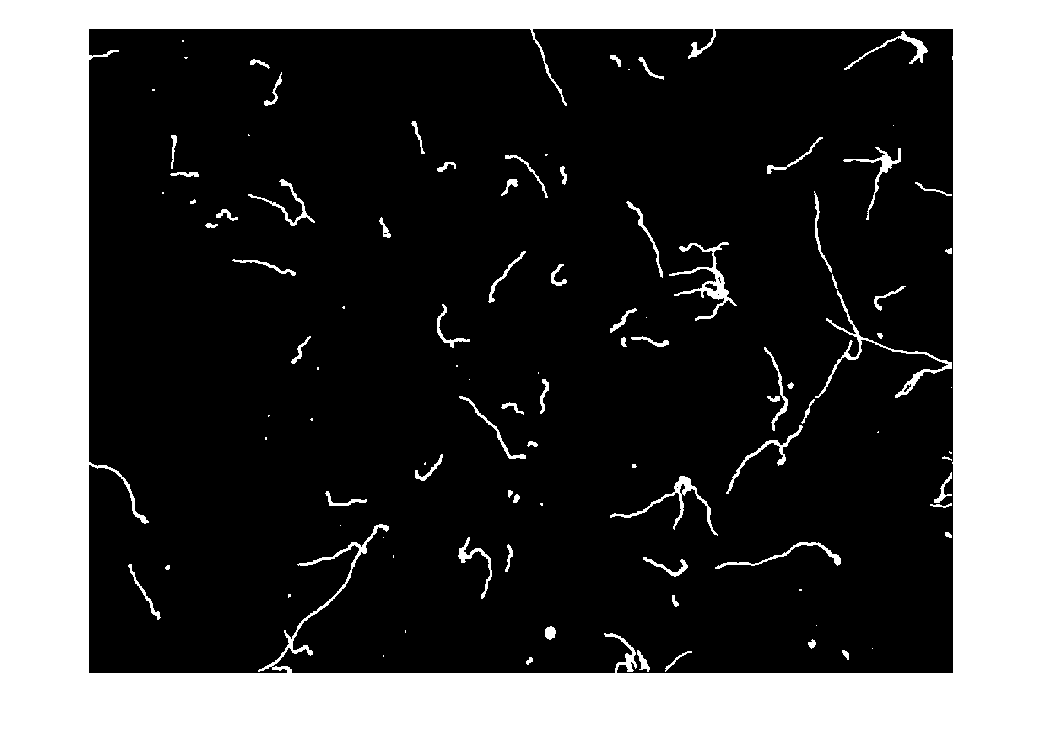

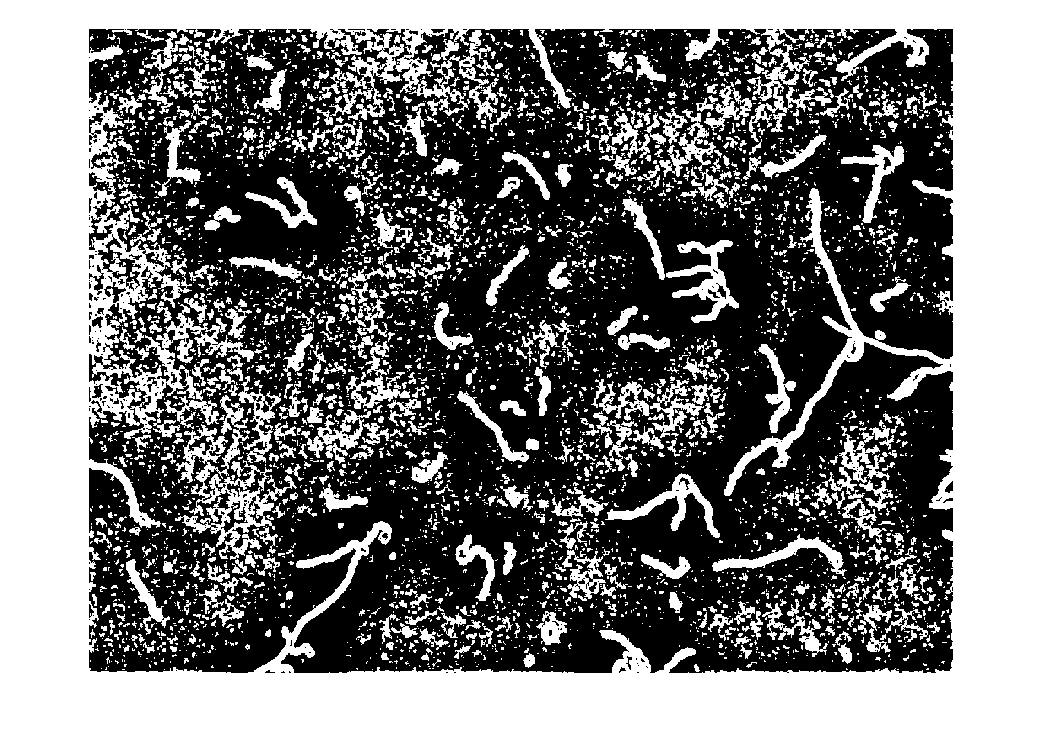

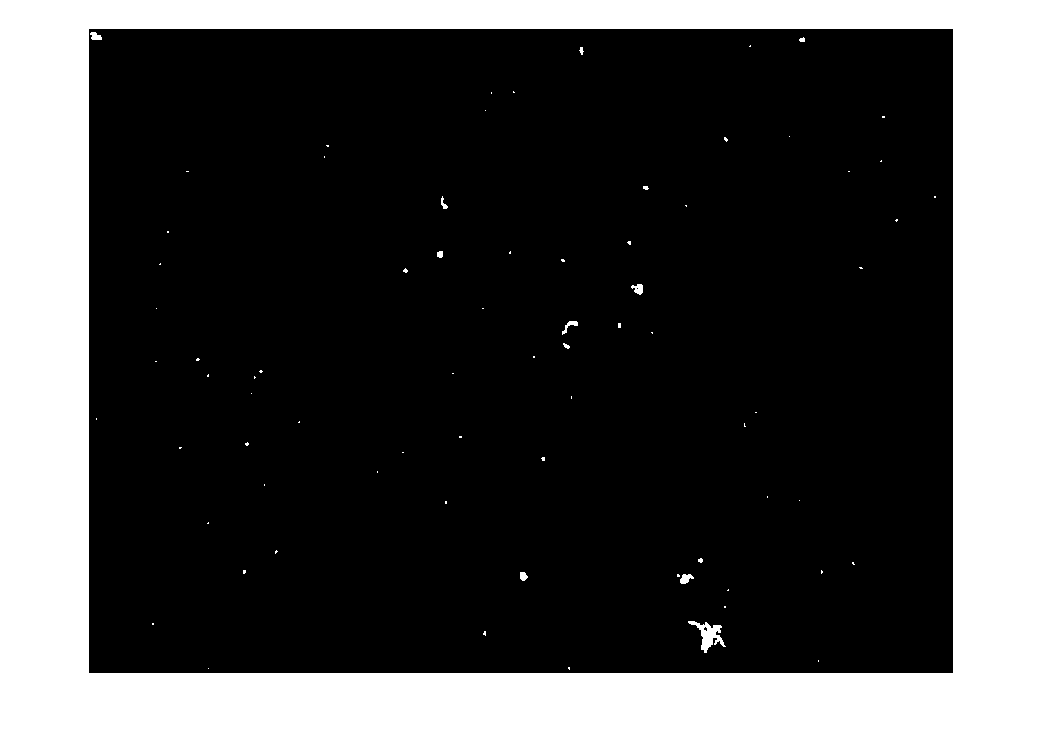

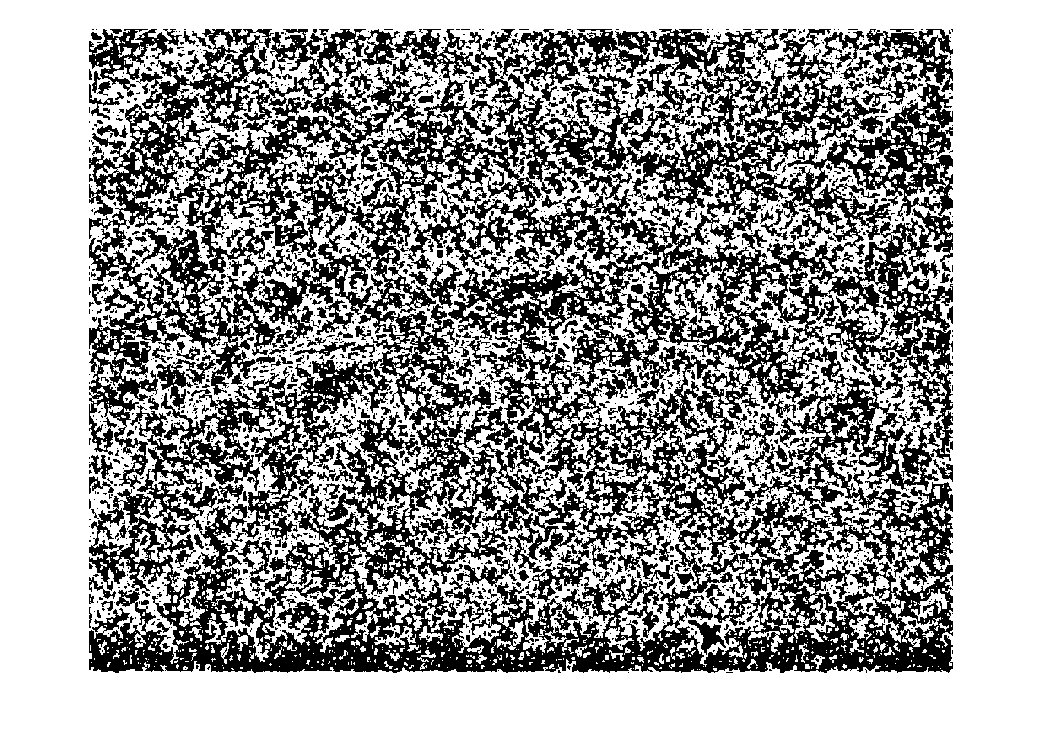

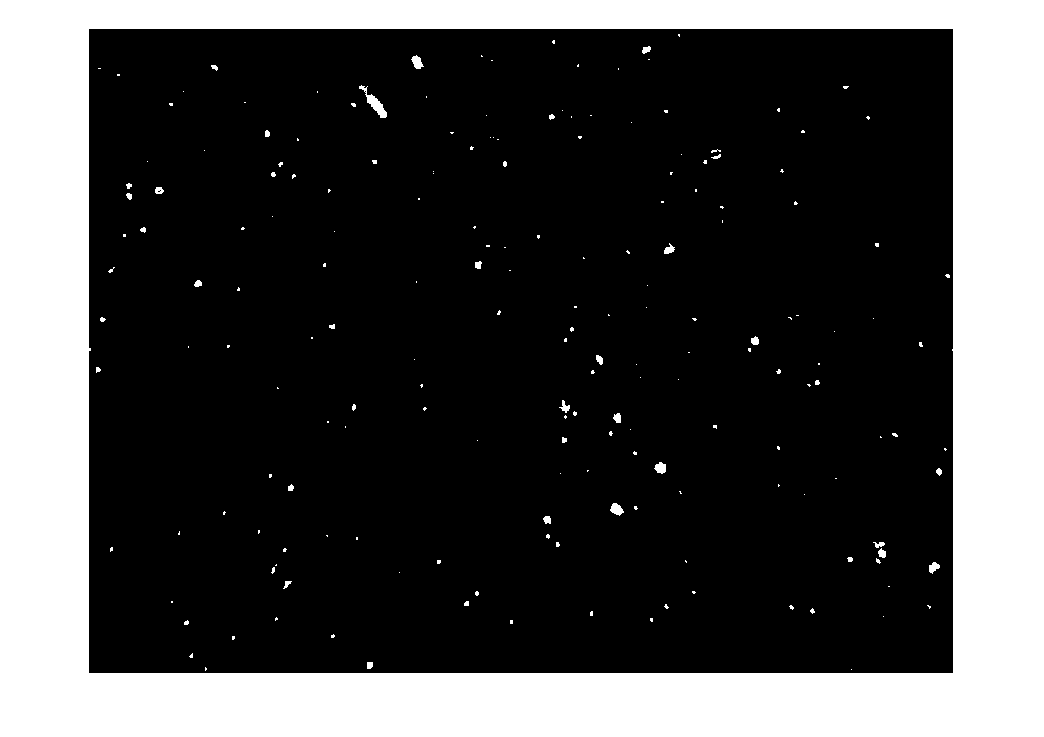

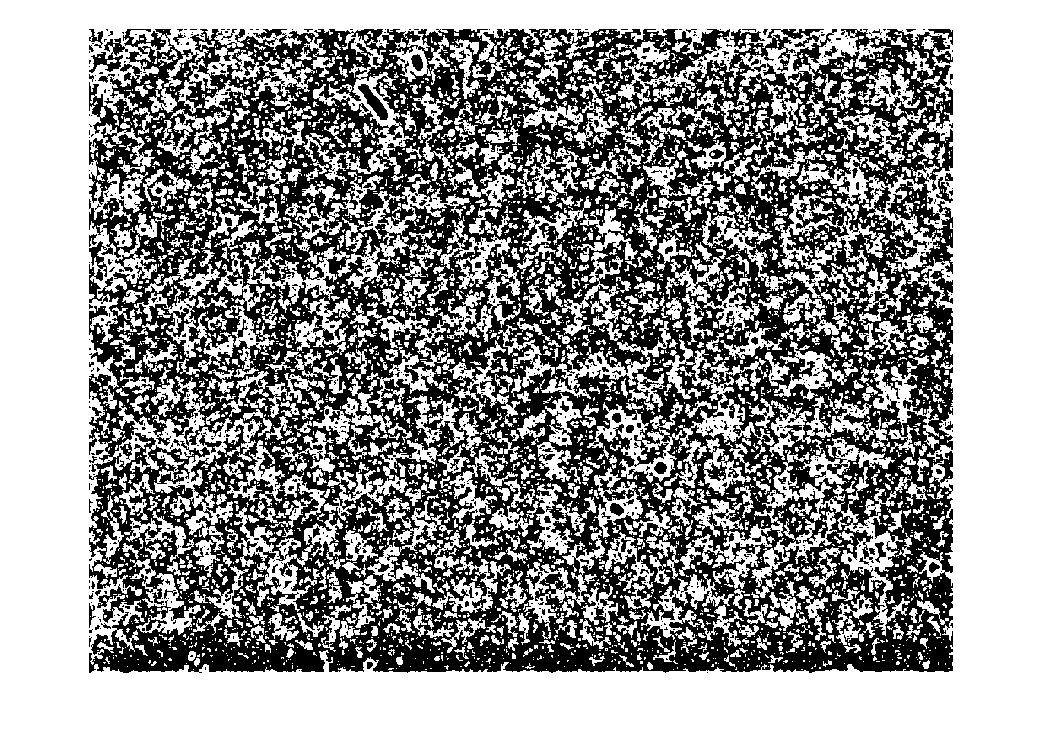

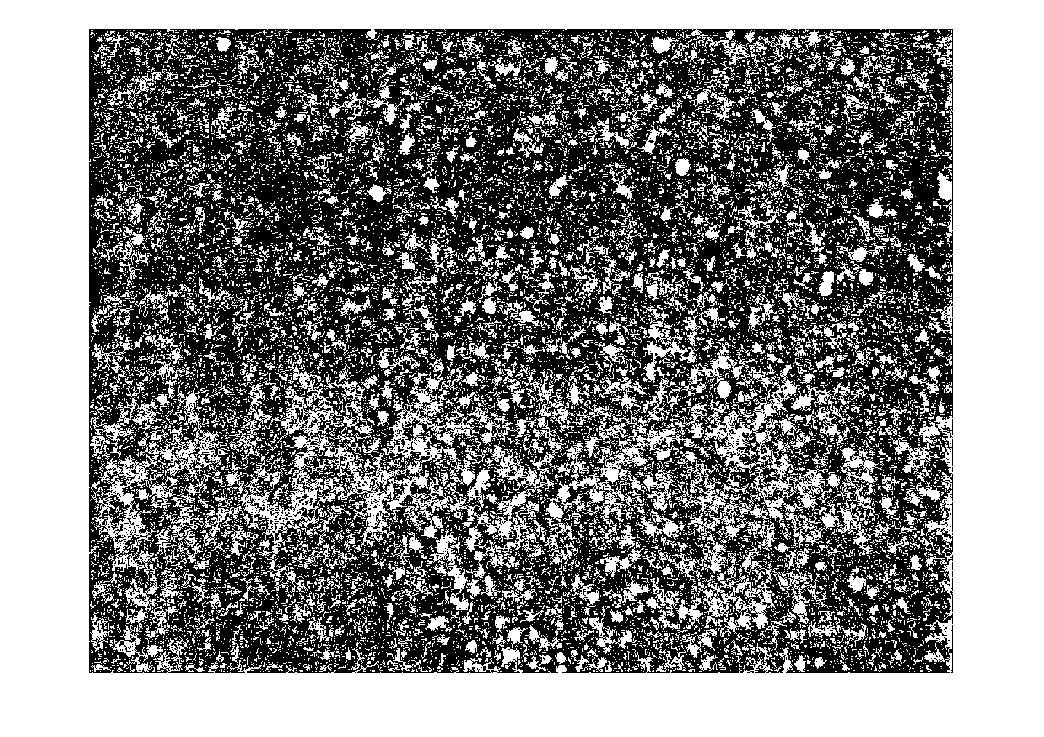

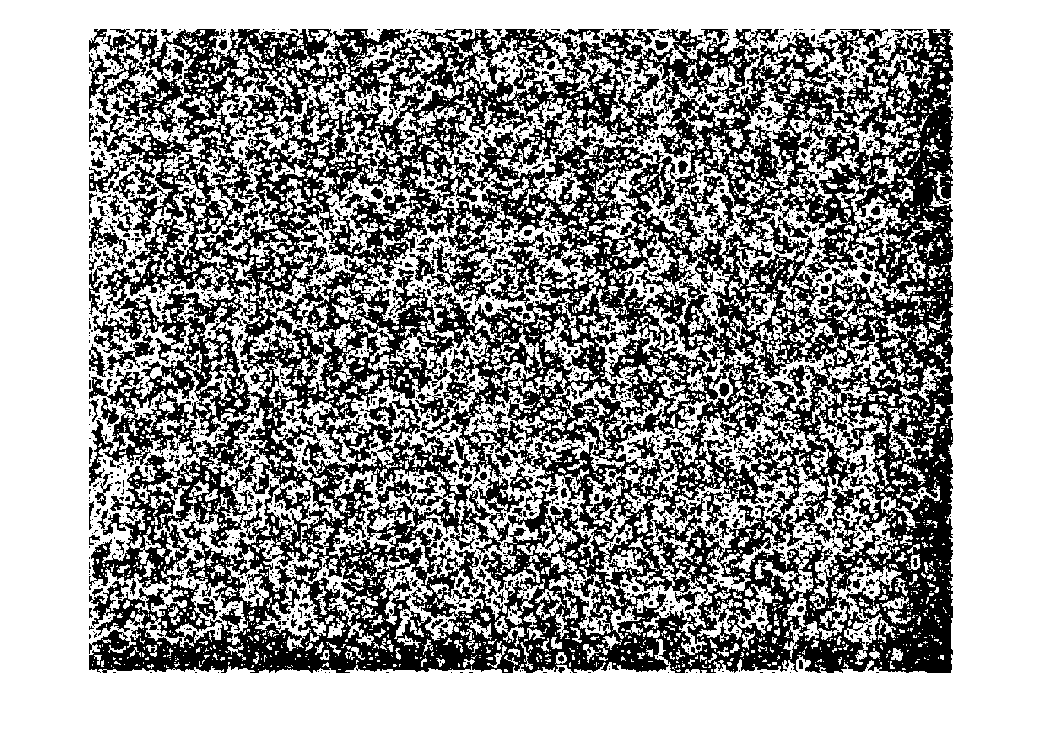

%STEP 1
%Upload images: open folder with the images of the sample
SporesImagesPath=fullfile('D:\Spores\Images\X40\G5004LD');
Images=imageDatastore(SporesImagesPath,'FileExtensions','.tif');

for i=1:numel(Images.Files)
    %STEP 2
    %Create BinaryImg1
    [I,info]=readimage(Images,i);
    Igray=rgb2gray(I);
    se=strel('disk',25);
    background=imclose(Igray,se);
    Im=background-Igray;
    Im=imcomplement(Im);
    BinaryImg1=imbinarize(Im);
    BinaryImg1=imcomplement(BinaryImg1);
    Bin1=BinaryImg1;  %create a copy of BinaryImg1
    
    %Create BinaryImg2
    IM=imadjust(Im);
    IM=mat2gray(IM);    
    IM=imadjust(IM);
    filteredImage = stdfilt(IM, ones(9));
    filteredImage=imcomplement(filteredImage);
    filteredImage=imbinarize(filteredImage,'adaptive','Sensitivity',0.6); 
    BinaryImg2=imcomplement(filteredImage);
    
    %preliminary computations for Step 3
    [count,pixels]=imhist(BinaryImg2);
    black=count(1);
    white=count(2);
    ratio=white/black;    
    
    if ratio>50
        BinaryImg2=imcomplement(BinaryImg2);
        [count,pixels]=imhist(BinaryImg2);
        black=count(1);
        white=count(2);
        ratio=white/black;
    end
    
    if ratio<0.5 %Test used for STEP 3
        %STEP 4
        ConnComp1=bwconncomp(BinaryImg2,4);
        N_1=ConnComp1.NumObjects;
        stat_1=regionprops(ConnComp1,'all');            
        for j=1:N_1   
            x=stat_1(j).PixelList(:,1);
            y=stat_1(j).PixelList(:,2);         
            if stat_1(j).Area<=1000   %find not germinated spores & leftovers               
                BinaryImg1(y,x)=0;    %delete them from binary image     
                Bin1(y,x)=0;
            end 
            if  stat_1(j).Extent>=0.7 %find not germinated spores & leftovers
                BinaryImg1(y,x)=0;    %delete them from binary image
                Bin1(y,x)=0;
            end
        end    
        
        ConnComp=bwconncomp(BinaryImg1,4);
        N=ConnComp.NumObjects;        
        stat=regionprops(ConnComp,'all');         
        for j=1:N     
            if  stat(j).Area<=400    %find not germinated spores & leftovers     
                x=stat(j).PixelList(:,1);
                y=stat(j).PixelList(:,2);   
                BinaryImg1(y,x)=0;   %delete them from binary image
                Bin1(y,x)=0;
            end
        end
        
        ConnComp=bwconncomp(BinaryImg1,4);
        N=ConnComp.NumObjects;        
        stat=regionprops(ConnComp,'all');        
        for j=1:N                            
            if  stat(j).Extent>=0.7  %find not germinated spores & leftovers          
                x=stat(j).PixelList(:,1);
                y=stat(j).PixelList(:,2);
                BinaryImg1(y,x)=0;   %delete them from binary image
                Bin1(y,x)=0;
            end
        end
        
        %find spores
        [CentersAll,RadiiAll]=imfindcircles(Bin1,[6 12],'Sensitivity',0.93,'EdgeThreshold',...
            0.89,'ObjectPolarity','bright'); 
        TotNumGerminatedSpores=numel(RadiiAll);
        
        %STEP 5
        %remove edge touching elements
        [count,pixels]=imhist(BinaryImg1);
        white=count(2);
        Threshold=(30*white)/100; 
        
        Cleaned=imclearborder(BinaryImg2,8);
        Edges=BinaryImg2-Cleaned;    
        Edges=imfill(Edges,'holes');
        Mask=logical(Edges);
        BinaryImg1(Mask)=0;
        BinaryImg1=imclearborder(BinaryImg1,8);
        [CountP1,Pixel1]=imhist(BinaryImg1);
        White1=CountP1(2);
        if White1<Threshold      
            BinaryImg1=Bin1;        %if removed too much than keep everything
        end
            
        %find remaining spores
        [Centers,Radii]=imfindcircles(BinaryImg1,[6 12],'Sensitivity',0.93,'EdgeThreshold',...
            0.89,'ObjectPolarity','bright');  %look for circles
        [columns rows]=meshgrid(1:size(BinaryImg1,2),1:size(BinaryImg1,1));
        figure;
        imshow(BinaryImg1);
        for k=1:numel(Radii)
            x=floor(Centers(k,1));          
            y=floor(Centers(k,2));
            viscircles([x y],Radii(k));
            array2D = (rows- y).^2+ (columns - x).^2<(Radii(k))^2;
            BinaryImg1(array2D)=0;   %mask pixels corresponding to spores 
        end 
        
        %STEP 6
        NumGerminatedSpores=numel(Radii)  %number of detected germinated spores after edge cleaning
        [CountPixels,PixelValue]=imhist(BinaryImg1);
        AreaGerminativeTubes=CountPixels(2);                 
        AverageTubeWidth=5;
        TotalLength=AreaGerminativeTubes/AverageTubeWidth;
        %STEP 7
        AverageLength=TotalLength/NumGerminatedSpores;        
    else
        %STEP 3
        [Centers,Radii]=imfindcircles(Igray,[6 16],'Sensitivity',0.8,...
            'EdgeThreshold',0.1,'ObjectPolarity','dark');
        [columns rows]=meshgrid(1:size(Bin,2),1:size(Bin,1));
        NumNotGerminatedSpores=numel(Radii);
    end
end